This project uses the linear noise degradation model to encrypt an image for secure transfer of sensitive pictures, documents, and other types of image data.

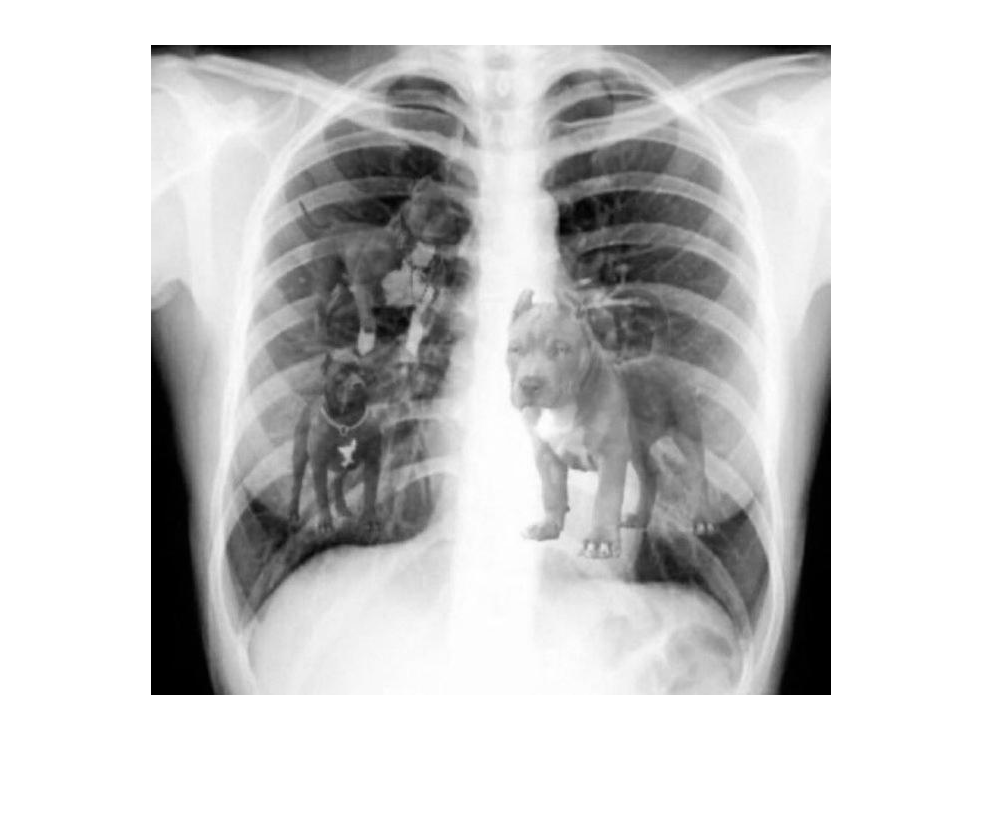

% Read in a test image
test_image = imread("eyobel_test_images\dawg.tif");
imshow(test_image)

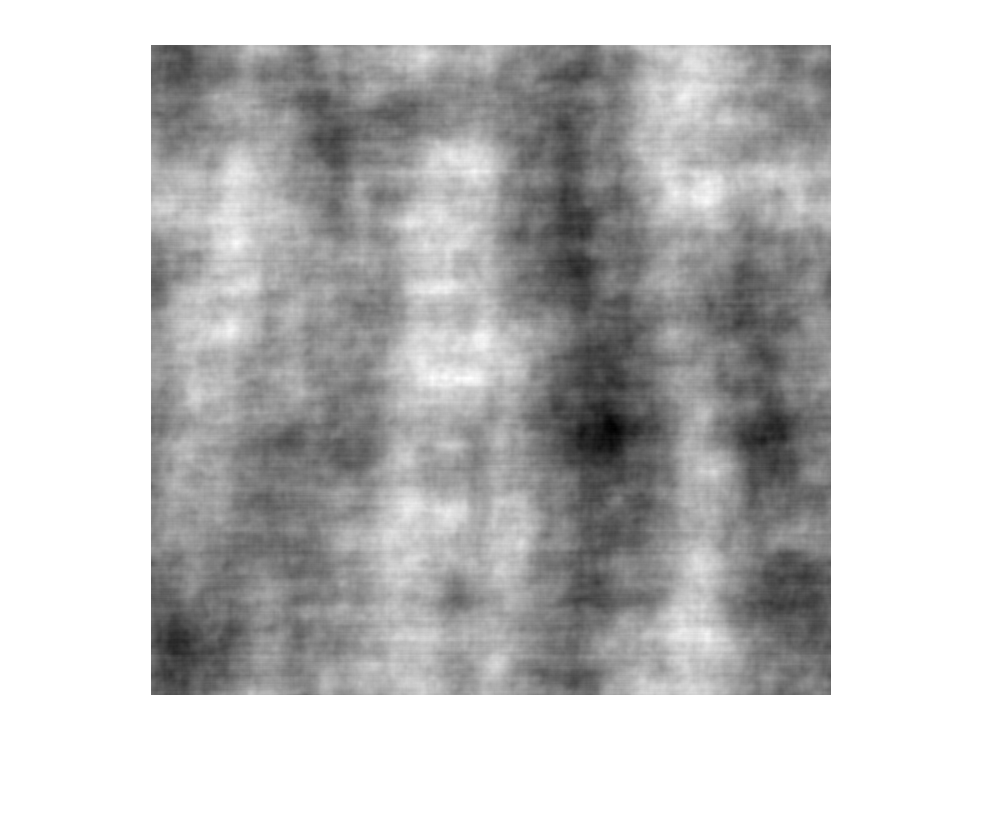


% Set p and g
prime = 251;
g = 5;

% Generate a private key for Alice and Bob
bob_key = privKeyGen(size(test_image,1), size(test_image,2));
alice_key = privKeyGen(size(test_image,1), size(test_image,2));

% Send the key to Alice
key_B = sendKey(g, prime, bob_key);

% Have Alice send her key to Bob
key_A = sendKey(g, prime, alice_key);

% Have Alice create a filter based on the key
alice_filt = filterGen(prime, alice_key, key_B);

% Apply the filter to the image
encrypted = encryptImage(test_image, alice_filt);

% Have Bob decrypt the message by creating his own filter to decrypt with
bob_filt = filterGen(prime, bob_key, key_A);
decrypted = decryptImage(encrypted, bob_filt);

% Show the resulting encrypted and decrypted images
imshow(encrypted, [])

imshow(decrypted, [])

First, we need a function to generate private keys

function private_key = privKeyGen(size1, size2)
    private_key = randi(255, size1, size2);
end

Next, we need a way to send private keys to other users.

function sent_key = sendKey(g, prime, private_key)
    sent_key = zeros(size(private_key,1), size(private_key,2));
    for i=1:size(private_key,1)
        for j=1:size(private_key,2)
            sent_key(i,j) = g;
            for mult=1:private_key(i,j)
                sent_key(i,j) = mod(sent_key(i,j) * g, prime);
            end
        end
    end
end

We also need a function to generate our random image noise and filter.

function filter = filterGen(prime, private_key, sent_key)
    filter = zeros(size(private_key,1), size(private_key,2));
    for i=1:size(private_key,1)
        for j=1:size(private_key,2)
            filt_val = sent_key(i,j);
            for mult=1:private_key(i,j)
                filt_val = mod(filt_val * sent_key(i,j), prime);
            end
            filter(i,j) = filt_val;
        end
    end
end

Next, we need to take these values and use them to form a new version of the fourier transform of our input image.

function encrypted_image = encryptImage(image, filter)
    % Generate fft versions of inputs
    fft_image = fft2(image);
    fft_filter = fft2(filter);
    
    % Calculate the altered image
    encrypted_image = fft_image.*fft_filter;
    encrypted_image = ifft2(encrypted_image);
end

Finally, we can write a function to decrypt the image based on the following:

function decrypted_image = decryptImage(image, filter)
    % Generate fft versions of inputs
    fft_image = fft2(image);
    fft_filter = fft2(filter);
    
    % Recalculate the original image
    decrypted_image = (fft_image) ./ fft_filter;
    decrypted_image = ifft2(decrypted_image);
end